 %harmonics generation
X = zeros(200,1280);
%X(2,:) = (1+a*(u(t-0.12)-u(t-0.22))).*x;
%X(1,:) = (1+a*(u(t-t1)-u(t-t2))).*x;

i = 1;
%for i = 1:200
    for a1 = 0.05:0.01:0.15     
        for a3 = 0.05:0.01:0.15     
            for a5 = 0.05:0.01:0.15
                for a7 = 0.05:0.01:0.15 
                    t = 0:0.0003125:0.4-0.0003125;
                    A = 1;
                    %a = 0.2;
                    f = 50;
                    w = 2*pi*f;
                    x = A*sin(w.*t);
                    u = inline('t>=0');
                    t1 = t2 - d;
                    X(i,:) = (a1*sin(w.*t)+a3*sin(3.*w.*t)+a5*sin(5.*w.*t)+a7*sin(7.*w.*t));
                    i = i+1;
                end
            end
        end
     end   
%end

X

X =          0    0.0747    0.1281    0.1470    0.1307    0.0905    0.0450    0.0115    0.0000    0.0095    0.0301    0.0484    0.0541    0.0446    0.0255    0.0074         0    0.0074    0.0255    0.0446    0.0541    0.0484    0.0301    0.0095    0.0000    0.0115    0.0450    0.0905    0.1307    0.1470    0.1281    0.0747   -0.0000   -0.0747   -0.1281   -0.1470   -0.1307   -0.0905   -0.0450   -0.0115   -0.0000   -0.0095   -0.0301   -0.0484   -0.0541   -0.0446   -0.0255   -0.0074         0   -0.0074
         0    0.0810    0.1380    0.1558    0.1345    0.0876    0.0367    0.0016   -0.0071    0.0085    0.0356    0.0580    0.0634    0.0493    0.0235   -0.0004   -0.0100   -0.0004    0.0235    0.0493    0.0634    0.0580    0.0356    0.0085   -0.0071    0.0016    0.0367    0.0876    0.1345    0.1558    0.1380    0.0810   -0.0000   -0.0810   -0.1380   -0.1558   -0.1345   -0.0876   -0.0367   -0.0016    0.0071   -0.0085   -0.0356   -0.0580   -0.0634   -0.0493   -0.0235    0.0004    0.0100    0

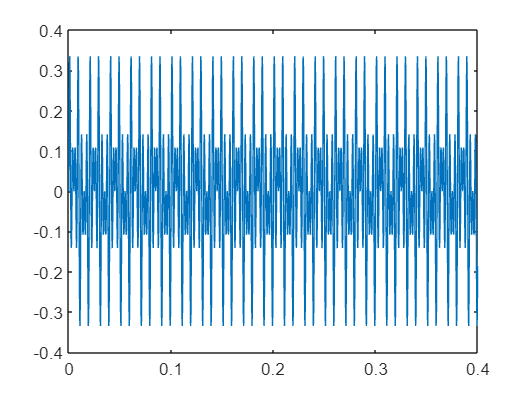

            
plot(t,X(121,:)) 

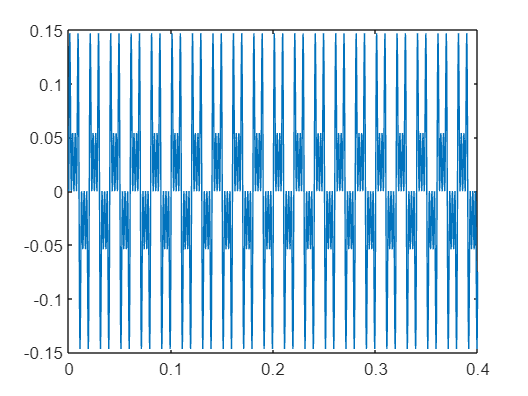

plot(t,X(1,:))

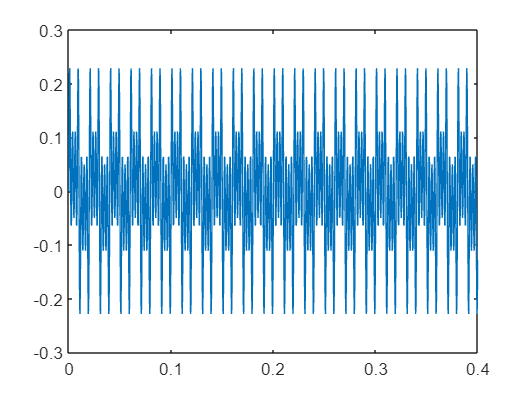

plot(t,X(30,:))

%X(167,:) = (1+a*(u(t-0.12)-u(t-0.22))).*x
%plot(t,x1)
